# FRSKIA001 Kian Frassek lab 2

## 1 prelab section 

###     FBD

        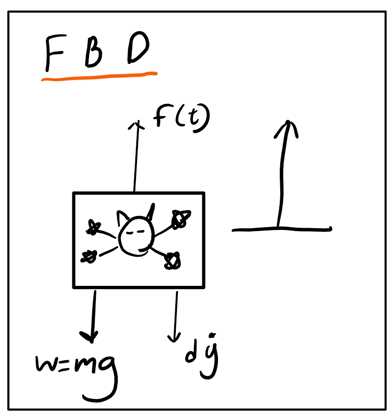

###     Block diagram

        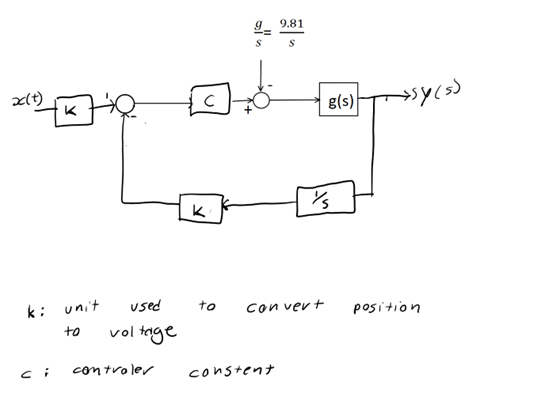

## 2 calculatin the culculatin the open loop respons

###     steps

-  Create a  array to store all the sets of arrays  for each unit step test.

-  created a loop to calculate the velocity of each response and add it to its appropriate array.   

- find the gain of each step

####     forules used

        
$$G\left(s\right)=\frac{A^{\prime } }{\tau s+1\;}=\frac{k\cdot \;B\cdot A}{\tau \;s+1}$$


        All plots have $A^{\prime } =4\ldotp 318$

        The average value of the time constant is $\tau =8\ldotp 9$

        The average value of the conversion constant is $k=0\ldotp 4298$ 

        $B$ is the magnitude of the input step: $B=5-2\ldotp 5=2\ldotp 5$

        
$$A^{\prime } =k\cdot \;B\cdot A\to 4\ldotp 318=0\ldotp 4298\cdot \;2\ldotp 5\cdot A\to A=4\ldotp 0186$$


        The transfer function is: $\frac{4\ldotp 318}{8\ldotp 9s+1}=\frac{0\ldotp 485}{s+0\ldotp 1124}$

        Therefore $b=0\ldotp 1124$

%_______________________________1____________________________
step_array_of_array = cell(3, 1);  % Create a cell array to store the data for each step

disp(" 1. collected all the arrays from CSV files");

 1. collected all the arrays from CSV files



%______________________________2________________________________
disp('# created a loop to calculate the velocity of each response and add it to its appropriate array.');

# created a loop to calculate the velocity of each response and add it to its appropriate array.


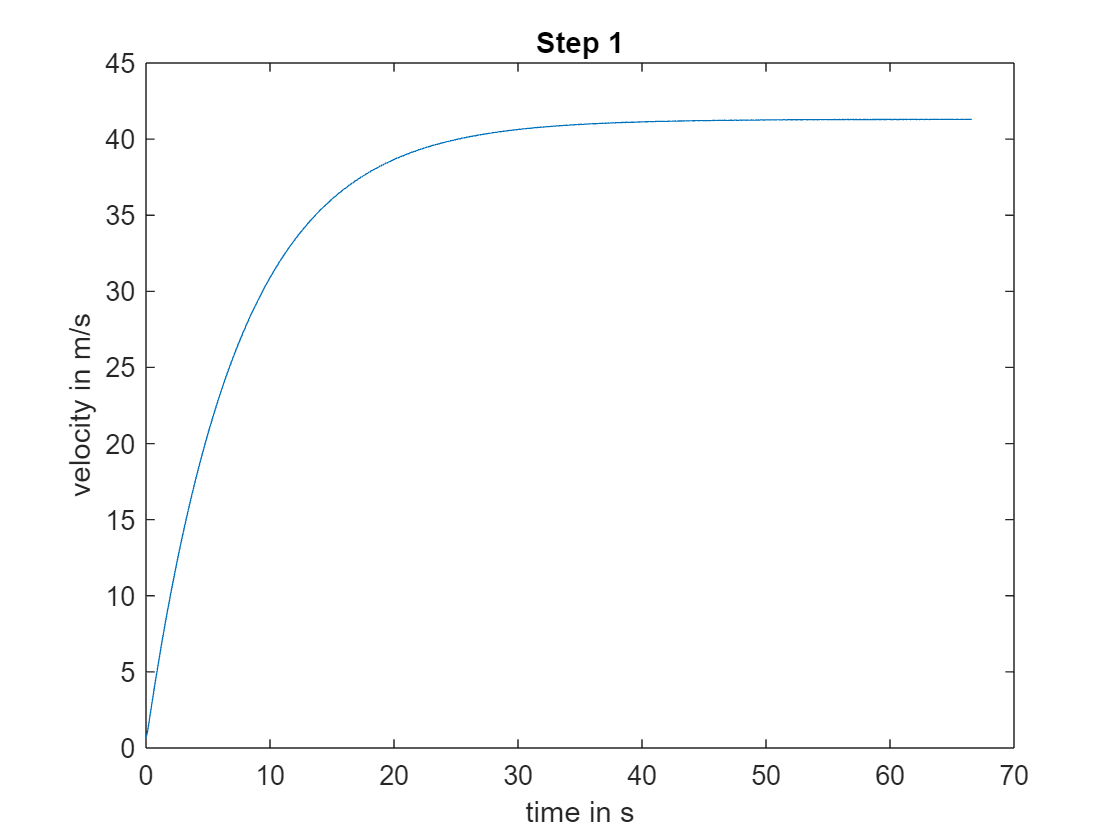

A_prime for 1 is 41.3


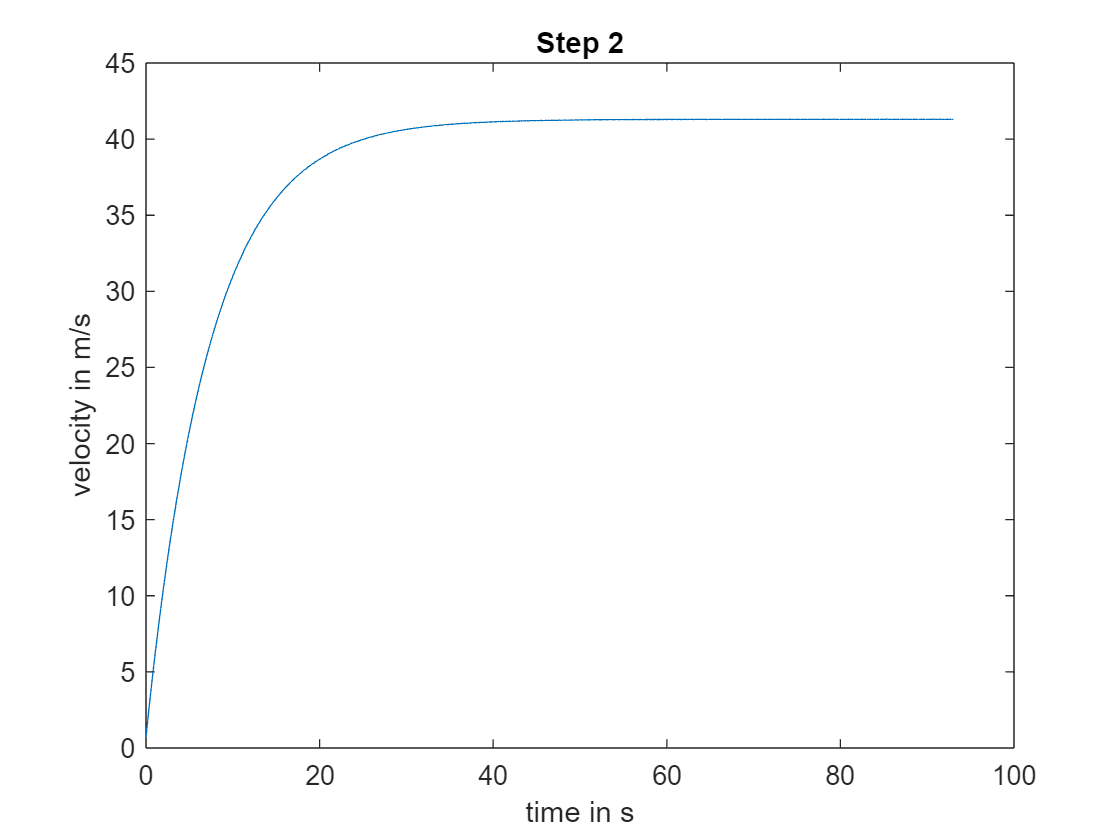

A_prime for 2 is 41.31


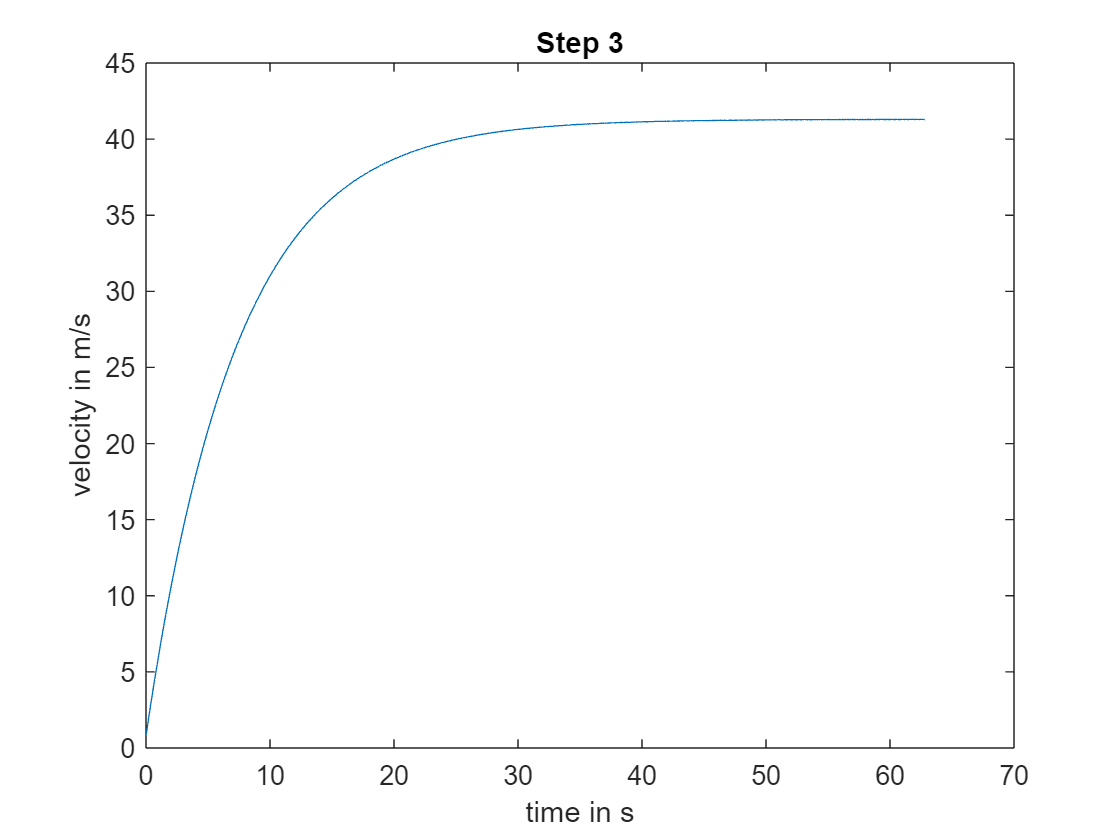

A_prime for 3 is 41.3



A_prime=[]; % creating Aprime 
start = [];
endin=[];


for step_number = 1:3
    % Read the data for the current step
    step_array_of_array = readmatrix(['step ', num2str(step_number), '.csv']);
    
    % Finding delta t and delta y
    delta_time = diff(step_array_of_array(:, 1));
    delta_position = diff(step_array_of_array(:, 4));
    
    velocities = [0; delta_position ./ delta_time];
    
    % Adding velocities to the main array
    step_array_of_array(:, 5) = velocities;
    
    % Isolating the data we want
    
    step_correct_start = [];
    time_start = 0;
    
    for i = 1:length(velocities)
        if (velocities(i) > 0.5) && (time_start == 0)
            time_start = step_array_of_array(i, 1);
        end
        
        if velocities(i) > 0.5
            step_correct_start = [step_correct_start; step_array_of_array(i, 1) - time_start , velocities(i)];
        end
    end
    
    % Store the corrected data for the current step in the cell array
    steps{step_number} = step_correct_start;
    
    % Plot the data for the current step
    figure;
    plot(steps{step_number}(:, 1), steps{step_number}(:, 2));
    title(['Step ', num2str(step_number)]);
    xlabel("time in s");
    ylabel("velocity in m/s");
     
    %calculatin the A_prime

    A_prime = [A_prime; max(steps{step_number}(:,2))]; %creating an arry with the averag values
    disp("A_prime for " + step_number + ' is ' + max(steps{step_number}(:, 2)));

    %calculatin the B

    start = [start; step_array_of_array(5,2)];
    endin=  [endin; step_array_of_array(500, 2) ];
    
       
end


% getting the averag value
A_prime_ave= mean(A_prime);
endin_ave = mean(endin);
start_ava = mean(start);
disp("A prime ave = " + A_prime_ave + newline + "final voltage in ave = " + endin_ave + newline + "intial voltage in = " + start_ava);

A prime ave = 41.3033
final voltage in ave = 5
intial voltage in = 2.502



$$G\left(s\right)=\frac{A_{\textrm{prime}} }{\tau s+1\;}=\frac{k\cdot \;B\cdot A}{\tau \;s+1}$$
